# **Lab 3 - Z-Transforms, Filters and Oscillators**

***By Jason Ha (z5115925)***

## **Question 1**

We are given the following first order digital filters in the $z$-domain:


$$H\left(z\right)=1-{\textrm{az}}^{-1}$$



$$G\left(z\right)=\frac{1}{1-{az}^{-1} }$$


Where $\left|a\right|<1$ to ensure convergence of the infinite series.

### Part (a)

We want to compute $h\left\lbrack n\right\rbrack$ and $g\left\lbrack n\right\rbrack$ for $a=\frac{1}{2}$ and $a=-\frac{1}{2}$ and compare the results obtained. We analyse these as two separate cases:

#### Case 1: $a=\frac{1}{2}$

$H\left(z\right)$ is a first-order *all-zero *filter which implies that it is a *finite-impulse response* (FIR) filter. We can deduce the impulse response to have only two non-zero samples:

$h\left\lbrack 0\right\rbrack =1$   and    $h\left\lbrack 1\right\rbrack =-\frac{1}{2}$

We can compute this impulse response using the *impz* function provided we have the poles and zeros of our transfer function. We will plot the impulse shortly after.

% Impulse response for h[n] (Case 1)
H1_num = [1, -1/2];
H1_den = 1;
h1 = impz(H1_num, H1_den);

On the other hand, $G\left(z\right)$ is a first-order all-pole filter. The equation is comparable to the general formula for the limiting sum of an infinite geometric series with an initial term $b=1$ and the ratio $r=\frac{1}{2}z^{-1}$. We can write the function alternatively as:


$$g\left\lbrack n\right\rbrack =1+\left(\frac{1}{2}\right)+{\left(\frac{1}{2}\right)}^{2\;} +{\left(\frac{1}{2}\right)}^{3\;} +\ldotp \ldotp \ldotp =\sum_{k=0}^{\infty \;} {\left(\frac{1}{2}\right)}^k$$


We can condense this by noting the filter being non-zero for all $n<0$ by using the unit-step function, $u\left\lbrack n\right\rbrack$


$$g\left\lbrack n\right\rbrack ={\left(\frac{1}{2}\right)}^n u\left\lbrack n\right\rbrack$$


This is an *infinite impulse response *(IIR) filter exhibits an exponential decay, for increasing values of $n$, towards $g\left\lbrack n\right\rbrack =0$. Like with $h\left\lbrack n\right\rbrack$, we can compute $g\left\lbrack n\right\rbrack$ using the *impz *function. 

% Impulse response for g[n] (Case 1)
G1_num = 1;
G1_den = [1, -1/2];
g1 = impz(G1_num, G1_den);

We can plot each of the impulse responses on a subplot figure and compare the impulse response of an FIR compared to an IIR:

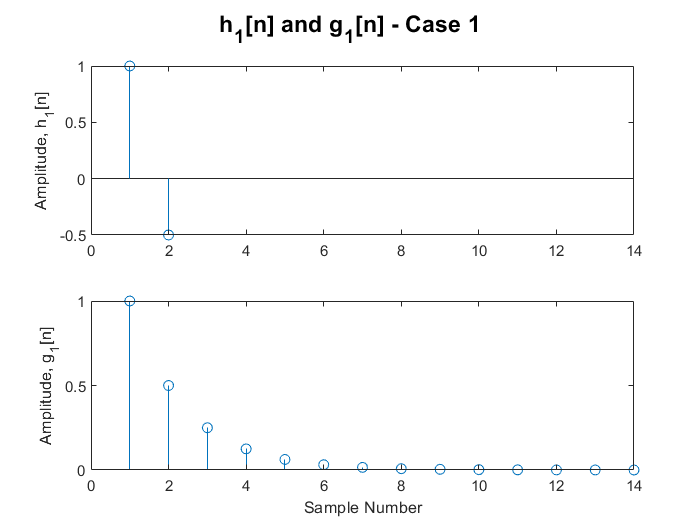

figure
subplot(2,1,1)
stem(h1)
ylabel('Amplitude, h_1[n]')
xlim([0,14])
subplot(2,1,2)
stem(g1)
xlabel('Sample Number')
ylabel('Amplitude, g_1[n]')
sgtitle("h_1[n] and g_1[n] - Case 1", 'fontweight', 'bold')

#### Case 2: $a=-\frac{1}{2}$ 

We now want to do the same thing but for when $a=-\frac{1}{2}$. It is clear that the impulse response for $h\left\lbrack n\right\rbrack$ will remain finite. The only difference is that the second sample has a positive amplitude instead of a negative one.


$$H\left(z\right)=1+\frac{1}{2}z^{-1} \;\;\;\;\Longrightarrow \;\;\;\;\;\;h\left\lbrack 0\right\rbrack =1\;\;\;\mathrm{and}\;\;\;\;h\left\lbrack 1\right\rbrack =\frac{1}{2}$$


However, $G\left(z\right)$ will exhibit an exponential


$$G\left(z\right)=\frac{1}{1+\frac{1}{2}z^{-1} }=\frac{1}{1-\left(-\frac{1}{2}z^{-1} \right)}$$


In recursive form, this would be expressed as:


$$G\left(z\right)=1+\left(-\frac{1}{2}z^{-1} \right)+{\left(-\frac{1}{2}z^{-1} \right)}^2 +{\left(-\frac{1}{2}z^{-1} \right)}^3 +\ldotp \ldotp \ldotp =\sum_{k=0}^{\infty \;} {\left(-\frac{1}{2}z^{-1} \right)}^k$$


It is implied that the impulse response would then be:


$$g\left\lbrack n\right\rbrack =1+\left(-\frac{1}{2}\right)+{\left(-\frac{1}{2}\right)}^2 +{\left(-\frac{1}{2}\right)}^3 +\ldotp \ldotp \ldotp =\sum_{k=0}^{\infty \;} {\left(-\frac{1}{2}\right)}^k$$


The equation suggest every even sample produces a positive amplitude while every odd sample produces a negative sample. As such, we expect some oscillatory behaviour for $g\left\lbrack n\right\rbrack$. 

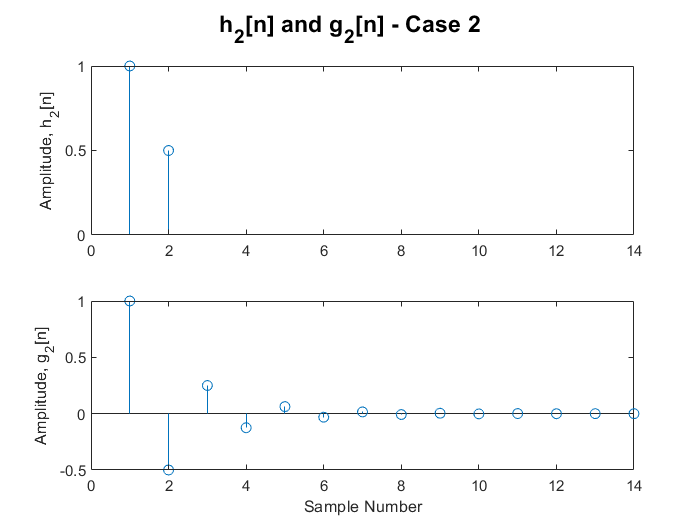

% Impulse response for h[n] (Case 2)
H2_num = [1, +1/2];
H2_den = 1;
h2 = impz(H2_num, H2_den);

% Impulse response for g[n] (Case 2)
G2_num = 1;
G2_den = [1, +1/2];
g2 = impz(G2_num, G2_den);

figure
subplot(2,1,1)
stem(h2)
ylabel('Amplitude, h_2[n]')
xlim([0,14])
subplot(2,1,2)
stem(g2)
xlabel('Sample Number')
ylabel('Amplitude, g_2[n]')
sgtitle("h_2[n] and g_2[n] - Case 2", 'fontweight', 'bold')